# **wavelet-RnB Live, version 02**

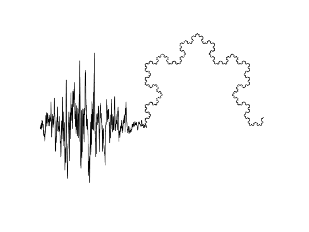

## *Fig.0 (the neural mass model) *

#### *(J.M. Lina, M-C. Foti, 2024)*

## This code solve the neural mass model EDP's with the canonical parameters (O. David et al., A neural mass model for MEG/EEG coupling and naural dynamics, 2003)

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024 

 
clc; clear; close all;
addpath('./ressources')
if ~isfile('./data/JansRit.mat')
fprintf(' -- This EDP solver may take a couple of minutes\n');
fprintf('    The simulation will produce a neural mass response\n');
fprintf('    for 8 seconds.\n');

tic
fs = 256; % sampling rate
N  = 8*fs; % duration
time = (0:N-1)/fs;
Nt   = length(time);
% Solver:
options = odeset('RelTol',1e-4,'AbsTol',[1e-4 1e-4 1e-4 1e-4 1e-4 1e-4]);
y0 = 100*[0 0 0 randn randn randn];
[t,y] = ode23(@edp_neural_mass,time,y0,options);
neural_mass_response = y(:,1);
save('./data/JansRit','t','neural_mass_response','fs');
tt = toc;
fprintf('    Elapsed time %3.2f minutes.\n',tt/60);
else
    load('./data/JansRit');
end
f1 = make_fig1(t,neural_mass_response);

## Spectral power of the canonical neural mass response: 

 
% signal selection:
Ntime  = 1024;
ta = find(t>2,1,'first');
time = t(ta+1:ta+Ntime);
signal = neural_mass_response(ta:ta+1023);

    % Fourier transform:
    
    Nfrac = Ntime/2+1;
    freq  = fs/2 * linspace(0,1,Nfrac);
    F     = fft(signal',Ntime)' ./ Ntime;
    % we only keep AC components
    F     = F(2:Nfrac);
    P     = abs(F).^2;
    freq  = freq(2:Nfrac); 
    % we keep frequencies > 1
    fsel = find((freq>1) & (freq<64));
    freq = freq(fsel);
    P    = P(fsel);

% Display 
f2 = make_fig2(time,signal,freq,P);
fprintf('\nBye.\n')
